Name: Krish Singh

Roll no: Bl.ai.u4aid25072

Lab Excercise 5

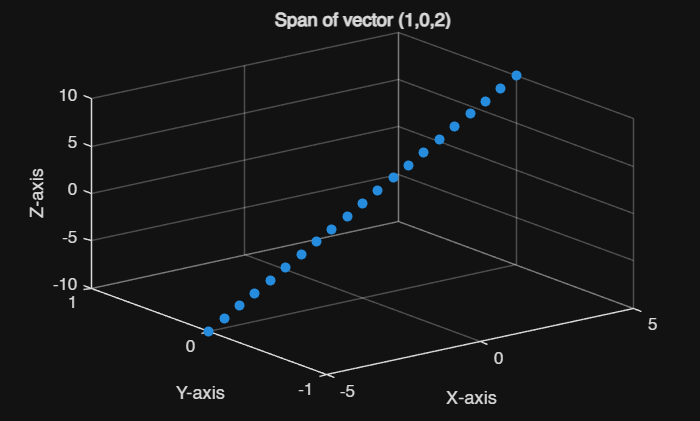

%qno 1
clf
v=[1 0 2];
t=-5:0.5:5;
P=t'*v;
scatter3(P(:,1), P(:,2), P(:,3), 'filled');
xlabel('X-axis');
ylabel('Y-axis');
zlabel('Z-axis');
title('Span of vector (1,0,2)');

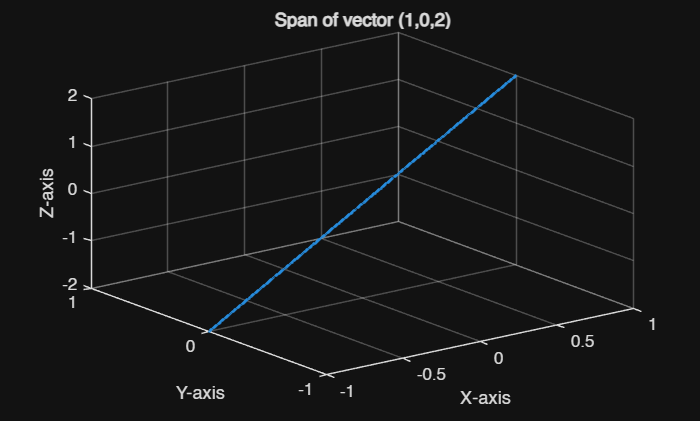

%another way to do it
b=[1;0;2];
pts=[];
for i=1:1000
    k1=-1+2*rand(1);
    pts=[pts,k1*b];
end
scatter3(pts(1,:),pts(2,:),pts(3,:),1);
xlabel('X-axis');
ylabel('Y-axis');
zlabel('Z-axis');
title('Span of vector (1,0,2)');

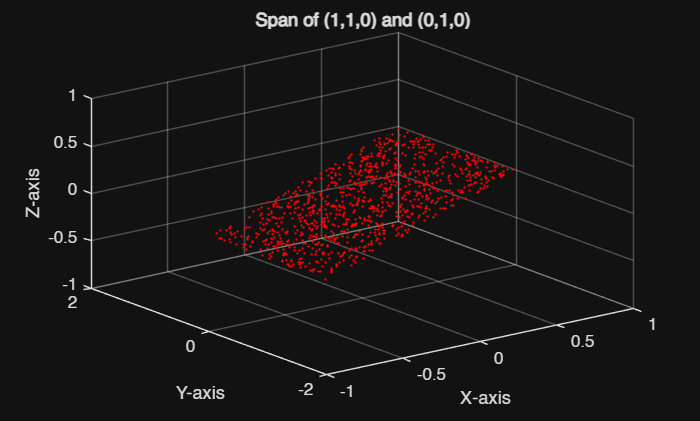

%Qno 2
b1=[1;1;0];
b2=[0;1;0];
pts=[];
for i=1:1000
    k1=-1+2*rand(1);
    k2=-1+2*rand(1);
    pts=[pts,k1*b1+k2*b2];
end
scatter3(pts(1,:),pts(2,:),pts(3,:),2,'filled','r');
xlabel('X-axis');
ylabel('Y-axis');
zlabel('Z-axis');
title('Span of (1,1,0) and (0,1,0)')

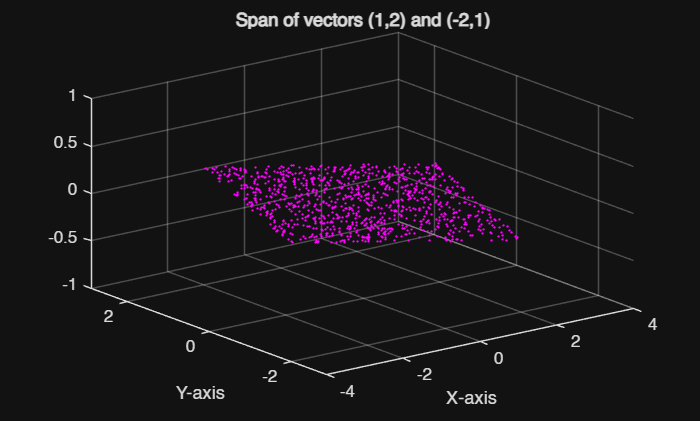

%Qno 2
b1=[1;2];
b2=[-2;1];
pts=[];
for i=1:1000
    k1=-1+2*rand(1);
    k2=-1+2*rand(1);
    pts=[pts,k1*b1+k2*b2];
end
scatter3(pts(1,:),pts(2,:),0,2,'filled','magenta');
xlabel('X-axis');
ylabel('Y-axis');
title('Span of vectors (1,2) and (-2,1)');
grid on

%Qno 4
clf
M=[1 0 0; 0 0 0; 0 0 3]

M =      1     0     0
     0     0     0
     0     0     3


[RR, ic]=rref(M)    

RR =      1     0     0
     0     0     1
     0     0     0


ic =      1     3


r = length(ic) 

r = 2

R=RR(1:r,:)

R =      1     0     0
     0     0     1


RSB1=(R(1,:))';
RSB2=(R(2,:))';  % generating basis vectors of row space and writing it as column vectors
nm=null(M)

nm =      0
     1
     0


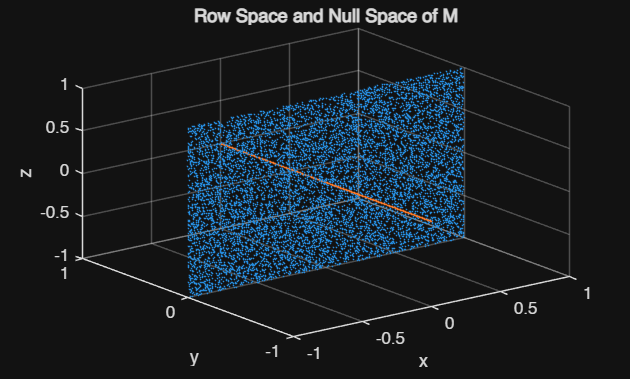

NSB1=(nm(:,1));  % generating basis vector of null space as column vector
RSpts=[]; 
NSpts=[];
for i=1:10000
    k1=-1+2*rand(1);
    k2=-1+2*rand(1);
    a1=-1+2*rand(1);
    RSpts=[RSpts,k1*RSB1+k2*RSB2];
    NSpts=[NSpts,a1*NSB1];
end
scatter3(RSpts(1,:),RSpts(2,:),RSpts(3,:),1,'filled');
hold on
scatter3(NSpts(1,:),NSpts(2,:),NSpts(3,:),1,"filled");
title('Row Space and Null Space of M');
xlabel('x'); 
ylabel('y'); 
zlabel('z');

%Qno 5
clf
a=[1,4;0,5];
b=[0,0;0,5];
c=[0,0;0,0];
[RRA,ica]=rref(a);
[RRB,icb]=rref(b);
[RRC,icc]=rref(c);
nmA=null(a);
nmB=null(b);
nmC=null(c);
disp("Nullspace of a:");disp(nmA);

Nullspace of a:


disp("Nullspace of b:");disp(nmB);

Nullspace of b:
     1
     0



disp("Nullspace of c:");disp(nmC);

Nullspace of c:
     1     0
     0     1



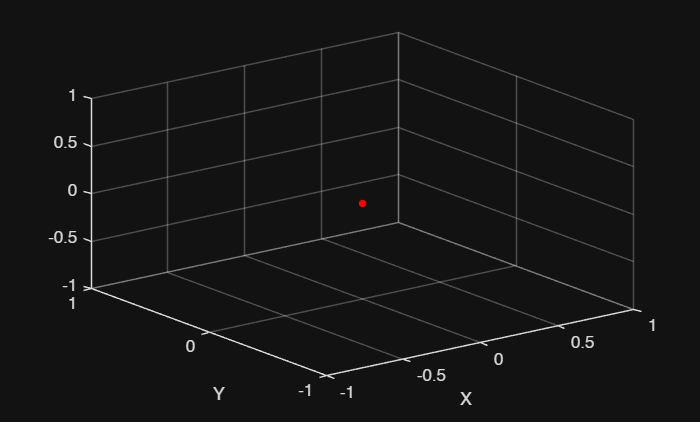

ptsa=[];
for i=1:1000
    if isempty(nmA)
        ptsa=[ptsa,[0;0]];
    else
    ka=-1+2*rand(1);
    ptsa=[ptsa, ka*nmA(:,1)];
    end
end
scatter3(ptsa(1,:),ptsa(2,:),0,20,'filled','MarkerFaceColor','r');
grid on
xlabel("X")
ylabel("Y")

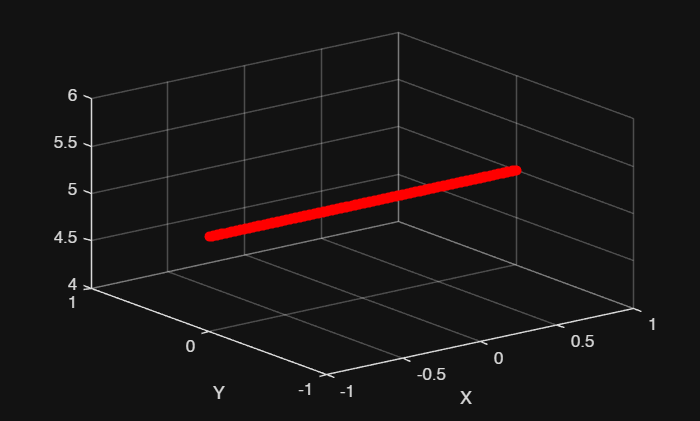

ptsb=[];
for i=1:1000
    if isempty(nmB)
        ptsb=[ptsb,[0;0]]
    else
        kb=-1+2*rand(1);
        ptsb=[ptsb,kb*nmB(:,1)];
    end
end
scatter3(ptsb(1,:),ptsb(2,:),5,'filled','r');
grid on
xlabel("X")
ylabel("Y")

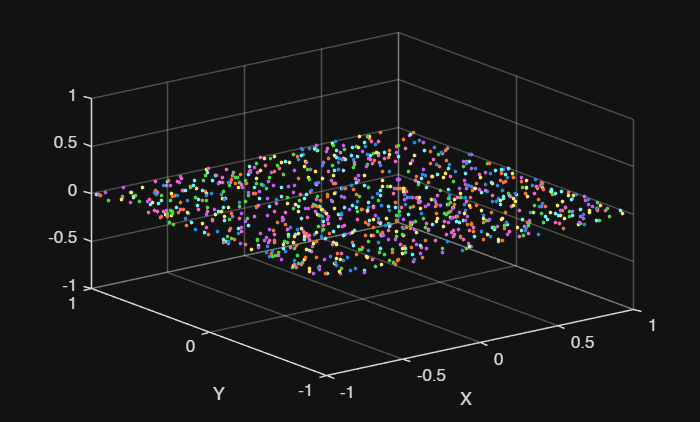

ptsc=[];
for i=1:1000
    if isempty(nmC)
        ptsc=[ptsc,[0;0]];
    else
        kc=-1+2*rand(1);
        kc2=-1+2*rand(1);
        ptsc=[ptsc,kc*nmC(:,1)+kc2*nmC(:,2)];
    end
end
scatter3(ptsc(1,:),ptsc(2,:),0,5,'filled')
grid on
xlabel("X")
ylabel("Y")

%Qno 6
clf
A=randi([1,10],3,2)*randi([1,9],2,3)

A =     50    36    42
    64    44    52
    47    64    65


[RRA,ica]=rref(A)

RRA =     1.0000         0    0.2308
         0    1.0000    0.8462
         0         0         0


ica =      1     2


Rank=length(ica)

Rank = 2

R=RRA(1:Rank,:)

R =     1.0000         0    0.2308
         0    1.0000    0.8462


RSB1=R(1,:)'

RSB1 =     1.0000
         0
    0.2308


RSB2=R(2,:)'

RSB2 =          0
    1.0000
    0.8462


[RRC,icc]=rref(A')

RRC =     1.0000         0   19.5000
         0    1.0000  -14.5000
         0         0         0


icc =      1     2


Rankc=length(icc)

Rankc = 2

RC=RRC(1:Rankc,:)

RC =     1.0000         0   19.5000
         0    1.0000  -14.5000


RCBS1=RC(1,:)'

RCBS1 =     1.0000
         0
   19.5000


RCBS2=RC(2,:)'

RCBS2 =          0
    1.0000
  -14.5000


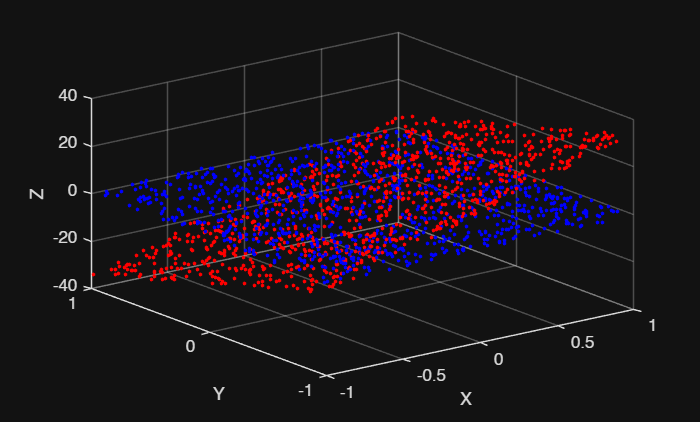

Rspts=[];
Cspts=[];
for i=1:1000
        a1=-1+2*rand(1);
        a2=-1+2*rand(1);
        Rspts=[Rspts,a1*RSB1+a2*RSB2];
        k1=-1+2*rand(1);
        k2=-1+2*rand(1);
        Cspts=[Cspts,k1*RCBS1+k2*RCBS2];
   
end
scatter3(Rspts(1,:),Rspts(2,:),Rspts(3,:),5,'filled','MarkerFaceColor','b');
hold on
scatter3(Cspts(1,:),Cspts(2,:),Cspts(3,:),5,'filled','MarkerFaceColor','r');
xlabel("X")
ylabel("Y")
zlabel("Z")
hold off

%QNo 7
clf
A=randi([1,9],3,1)*randi([1,9],1,3)

A =     54    36    18
    18    12     6
    30    20    10


[RA,ica]=rref(A')

RA =     1.0000    0.3333    0.5556
         0         0         0
         0         0         0


ica = 1

rank=length(ica);
Co=RA(1:rank,:);
CSB1=Co(1,:)'

CSB1 =     1.0000
    0.3333
    0.5556


na=null(A')

na =     0.5241   -0.1449
   -0.6446   -0.7115
   -0.5566    0.6876


nsb1=na(:,1)

nsb1 =     0.5241
   -0.6446
   -0.5566


nsb2=na(:,2)

nsb2 =    -0.1449
   -0.7115
    0.6876


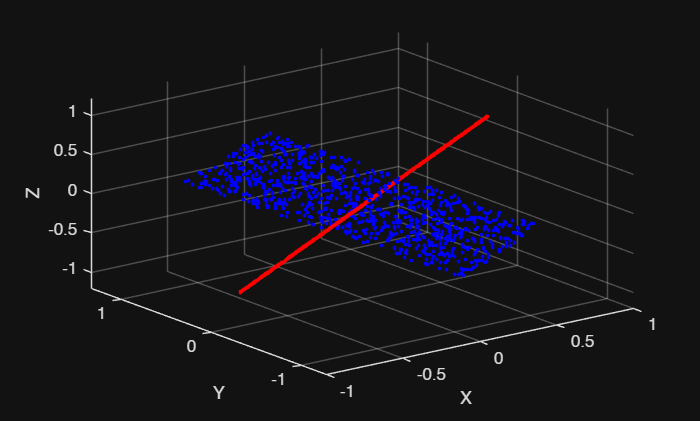

ptsc=[];
ptsn=[];
for i=1:1000
    a1=-1+2*rand(1);
    ptsc=[ptsc,a1*CSB1];
    k1=-1+2*rand(1);
    k2=-1+2*rand(1);
    ptsn=[ptsn,k1*nsb1+k2*nsb2];
end
scatter3(ptsc(1,:),ptsc(2,:),ptsc(3,:),5,'filled','MarkerFaceColor','r');
hold on
scatter3(ptsn(1,:),ptsn(2,:),ptsn(3,:),5,'filled','MarkerFaceColor','b');
grid on
hold off
xlabel("X")
ylabel("Y")
zlabel("Z")

%Qno 8
clc
clear
A=[1 3 4 7 ;2 4 6 10; 3 5 8 13; 4 6 10 16];
u=[-2;-3;1;1];
v=[5;8;11;14];
w=[1;1;2;3];
y=[1;2;0;-1];
m=[-1;1;1;-1];

% For vector u
if(rank([A,u])==rank(A))
    disp(u);disp(" u lies in column space of A")
elseif (rank([A;u'])==rank(A))
    disp(u);disp(" u lies in row space of A")
elseif norm(A*u)==0
    disp(u);disp(" u lies in null space of A")
elseif norm(u'*A)==0
    disp(u);disp(" u lies in Left Null space of A")
else
    disp("Vector u does not lie in subspace of A")
end

    -2
    -3
     1
     1

 u lies in null space of A



% For vector v
if(rank([A,v])==rank(A))
    disp(v);disp(" v lies in column space of A")
elseif (rank([A;v'])==rank(A))
    disp(v);disp(" v lies in row space of A")
elseif norm(A*v)==0
    disp(v);disp(" v lies in null space of A")
elseif norm(v'*A)==0
    disp(v);disp(" v lies in Left Null space of A")
else
    disp("Vector v does not lie in subspace of A")
end

     5
     8
    11
    14

 v lies in column space of A



% For vector w
if(rank([A,w])==rank(A))
    disp(w);disp(" w lies in column space of A")
elseif (rank([A;w'])==rank(A))
    disp(w);disp(" w lies in row space of A")
elseif norm(A*w)==0
    disp(w);disp(" w lies in null space of A")
elseif norm(w'*A)==0
    disp(w);disp(" lies in Left Null space of A")
else
    disp("Vector w does not lie in subspace of A")
end

     1
     1
     2
     3

 w lies in row space of A



% For vector y
if(rank([A,y])==rank(A))
    disp(y);disp(" y lies in column space of A")
elseif (rank([A;y'])==rank(A))
    disp(y);disp(" y lies in row space of A")
elseif norm(A*y)==0
    disp(y);disp(" y lies in null space of A")
elseif norm(y'*A)==0
    disp(y);disp(" y lies in Left Null space of A")
else
    disp("Vector y does not lie in subspace of A")
end

     1
     2
     0
    -1

 y lies in null space of A



% For vector m
if(rank([A,m])==rank(A))
    disp(m);disp(" m lies in column space of A")
elseif (rank([A;m'])==rank(A))
    disp(m);disp(" m lies in row space of A")
elseif norm(A*m)==0
    disp(m);disp(" m lies in null space of A")
elseif norm(m'*A)==0
    disp(m);disp(" m lies in Left Null space of A")
else
    disp("Vector m does not lie in subspace of A")
end

    -1
     1
     1
    -1

 m lies in Left Null space of A


%Qno 9
clc
clear
A=[1 -1 2 3; 0 2 1 4; 1 1 3 1; 2 0 5 4];
v=[5;1;-2;0];
w=[0;2;2;2];
u=[-1;2;-1;1];
m=[3;-1;7;7];

if(rank([A,v])==rank(A))
    disp(v);disp("v lies in column space of A");
elseif(rank([A;v'])==rank(A))
    disp(v);disp("v lies in row space of A");
elseif(A*v==0)
    disp(v);disp("v lies in null space of A");
elseif(v'*A==0)
    disp(v);disp("v lies in left null space of A");
else
    disp(v);disp("v doesnot lie in subspopace of A");
end

     5
     1
    -2
     0

v lies in null space of A



if(rank([A,w])==rank(A))
    disp(w);disp("w lies in column space of A");
elseif(rank([A;w'])==rank(A))
    disp(w);disp("w lies in row space of A");
elseif(A*w==0)
    disp(w);disp("w lies in null space of A");
elseif(w'*A==0)
    disp(w);disp("w lies in left null space of A");
else
    disp(w);disp("w doesnot lie in subspopace of A");
end

     0
     2
     2
     2

w lies in column space of A



if(rank([A,u])==rank(A))
    disp(u);disp("u lies in column space of A");
elseif(rank([A;u'])==rank(A))
    disp(u);disp("u lies in row space of A");
elseif(A*u==0)
    disp(u);disp("u lies in null space of A");
elseif(u'*A==0)
    disp(u);disp("u lies in left null space of A");
else
    disp(u);disp("u doesnot lie in subspopace of A");
end

    -1
     2
    -1
     1

u doesnot lie in subspopace of A



if(rank([A,m])==rank(A))
    disp(m);disp("m lies in column space of A");
elseif(rank([A;m'])==rank(A))
    disp(m);disp("m lies in row space of A");
elseif(A*m==0)
    disp(m);disp("m lies in null space of A");
elseif(m'*A==0)
    disp(m);disp("m lies in left null space of A");
else
    disp(m);disp("m doesnot lie in subspopace of A");
end

     3
    -1
     7
     7

m lies in row space of A


%Qno 10
A=randi([1,9],9,2)*randi([1,9],2,9);
rank(A)

ans = 2

%Qno 10 a
B=A+A'

B =     76    60    68   111   108   125    82   102    34
    60    24    57   103   102    97    50    53    23
    68    57    30    90    82    55    40   104    38
   111   103    90   158   149   178   117   145    51
   108   102    82   149   140   161   110   152    52
   125    97    55   178   161   106    63   158    66
    82    50    40   117   110    63    40   116    44
   102    53   104   145   152   158   116   178    48
    34    23    38    51    52    66    44    48    14


rank(B)

ans = 4

%QNo 10 b
[V,D]=eig(B)

V =    -0.2356   -0.0018    0.1583    0.8345    0.2403   -0.1888    0.1582    0.1079    0.3050
   -0.1750    0.7389   -0.1744   -0.0612   -0.3569    0.0664    0.1239    0.4340    0.2318
    0.3519   -0.2181   -0.6651    0.2470   -0.4476   -0.2074    0.0029   -0.1766    0.2251
   -0.2826   -0.3084   -0.4327   -0.3472    0.4694    0.0125    0.0867    0.3146    0.4362
   -0.1578   -0.4385    0.3887   -0.0443   -0.5311    0.4018    0.0117    0.1081    0.4176
    0.6093    0.0502    0.3866   -0.2046    0.0944   -0.4587   -0.0255    0.2253    0.4052
    0.4459    0.2233   -0.0823    0.1580    0.3206    0.7081   -0.1332   -0.1610    0.2681
   -0.2661    0.2487    0.0855   -0.2176    0.0132   -0.1628    0.1566   -0.7625    0.4243
   -0.2106    0.0699   -0.0178    0.0468   -0.0169   -0.1306   -0.9534   -0.0051    0.1477


D =  -108.3935         0         0         0         0         0         0         0         0
         0  -54.7825         0         0         0         0         0         0         0
         0         0   -0.0000         0         0         0         0         0         0
         0         0         0   -0.0000         0         0         0         0         0
         0         0         0         0   -0.0000         0         0         0         0
         0         0         0         0         0    0.0000         0         0         0
         0         0         0         0         0         0    0.0000         0         0
         0         0         0         0         0         0         0   54.2237         0
         0         0         0         0         0         0         0         0  874.9523


for i=1:9
    fprintf("Eigen Vectors %d is :",i)
    disp(V(:,i))
end

Eigen Vectors 1 is :

   -0.2356
   -0.1750
    0.3519
   -0.2826
   -0.1578
    0.6093
    0.4459
   -0.2661
   -0.2106



Eigen Vectors 2 is :

   -0.0018
    0.7389
   -0.2181
   -0.3084
   -0.4385
    0.0502
    0.2233
    0.2487
    0.0699



Eigen Vectors 3 is :

    0.1583
   -0.1744
   -0.6651
   -0.4327
    0.3887
    0.3866
   -0.0823
    0.0855
   -0.0178



Eigen Vectors 4 is :

    0.8345
   -0.0612
    0.2470
   -0.3472
   -0.0443
   -0.2046
    0.1580
   -0.2176
    0.0468



Eigen Vectors 5 is :

    0.2403
   -0.3569
   -0.4476
    0.4694
   -0.5311
    0.0944
    0.3206
    0.0132
   -0.0169



Eigen Vectors 6 is :

   -0.1888
    0.0664
   -0.2074
    0.0125
    0.4018
   -0.4587
    0.7081
   -0.1628
   -0.1306



Eigen Vectors 7 is :

    0.1582
    0.1239
    0.0029
    0.0867
    0.0117
   -0.0255
   -0.1332
    0.1566
   -0.9534



Eigen Vectors 8 is :

    0.1079
    0.4340
   -0.1766
    0.3146
    0.1081
    0.2253
   -0.1610
   -0.7625
   -0.0051



Eigen Vectors 9 is :

    0.3050
    0.2318
    0.2251
    0.4362
    0.4176
    0.4052
    0.2681
    0.4243
    0.1477



for i=1:9
    fprintf("Eigenvalue %d is:",i)
    disp(D(i,i))
end

Eigenvalue 1 is:

 -108.3935



Eigenvalue 2 is:

  -54.7825



Eigenvalue 3 is:

  -1.4679e-14



Eigenvalue 4 is:

  -1.0494e-14



Eigenvalue 5 is:

  -1.0350e-15



Eigenvalue 6 is:

   9.6392e-15



Eigenvalue 7 is:

   7.9717e-14



Eigenvalue 8 is:

   54.2237



Eigenvalue 9 is:

  874.9523



Eign=eig(B);
if all(isreal(Eign))
    disp("All Eigenvalues are real numbers");
else
    disp("There are complex Eigenvalues");
end

All Eigenvalues are real numbers


fprintf('A symmetric matrix has real eigenvalues because')

A symmetric matrix has real eigenvalues because

%Qbo 10d
count=0;
for i=1:9
    if abs(Eign(i))<1e-6||abs(Eign(i))<-1e-6
        count=count+1;
    else
        continue
    end
end
fprintf("number of Zero eigen values is : %d",count);

number of Zero eigen values is : 5

fprintf("Relation: Number of zero eigenvalues = size(B,1) - rank(B)"); %number of 0 eigen values=n-r

Relation: Number of zero eigenvalues = size(B,1) - rank(B)

%Qno 10 e
check=V'*V;
if norm(check - eye(size(check)))<1e-6
    disp("Eigenvectors are orthonormal to B")
else
    disp("Eigenvectors are not orthonormal to B")
end

Eigenvectors are orthonormal to B


%Qno 10 f
[RRA,ica]=rref(B);
[RRC,icc]=rref(B');
nb=null(B)

nb =     0.9146    0.0051    0.0558    0.0091    0.0115
   -0.1898    0.1090    0.3242   -0.1245   -0.1133
   -0.0178    0.0655    0.8304    0.2263    0.0378
   -0.2481   -0.2506   -0.1352    0.5525   -0.2964
   -0.1893    0.4571   -0.0175   -0.5929    0.0110
    0.0104   -0.4934   -0.2122   -0.2458    0.2495
    0.0631    0.6021   -0.3622    0.3263   -0.2222
   -0.1132   -0.2652   -0.0440   -0.1217   -0.0776
   -0.1135    0.1889   -0.0749    0.3078    0.8832


ranka=length(ica)

ranka = 4

rankc=length(icc)

rankc = 4

RA=RRA(1:ranka,:)

RA =     1.0000         0         0         0    0.4090   -2.0638    0.3437    6.1975    1.1959
         0    1.0000         0         0   -0.2395    0.9689    0.4603   -0.8305   -0.0995
         0         0    1.0000         0    0.2457    1.6423    1.2939    0.4494   -0.1446
         0         0         0    1.0000    0.6719    1.0093   -0.5381   -3.1509   -0.3701


RB=RRC(1:rankc,:)

RB =     1.0000         0         0         0    0.4090   -2.0638    0.3437    6.1975    1.1959
         0    1.0000         0         0   -0.2395    0.9689    0.4603   -0.8305   -0.0995
         0         0    1.0000         0    0.2457    1.6423    1.2939    0.4494   -0.1446
         0         0         0    1.0000    0.6719    1.0093   -0.5381   -3.1509   -0.3701


%Qno 10 g
NullityA=size(A,1)-rank(A);
NullityB=size(B,1)-rank(B);
fprintf("Nullity of A is: %d",NullityA)

Nullity of A is: 7

fprintf("Nullity of B is: %d",NullityB)

Nullity of B is: 5

%Qno 11
A=randi([1 9],10,3)*randi([1 9],3,5);
rank(A)

ans = 3

%Qno 11 a
S1=A*A'

S1 =        61071       43574       75590       70764       42005       51783       33932       29899       40174       27486
       43574       31131       53842       50276       29796       36769       24046       21311       28732       19528
       75590       53842       93767       88061       52393       64510       42395       37069       49569       34216
       70764       50276       88061       83111       49573       60918       40157       34751       46199       32276
       42005       29796       52393       49573       29690       36457       24163       20712       27323       19302
       51783       36769       64510       60918       36457       44802       29668       25526       33740       23730
       33932       24046       42395       40157       24163       29668       19787       16819       22005       15700
       29899       21311       37069       34751       20712       25526       16819       14701       19613       13542
       40174       28732   

S2=A'*A

S2 =       100907       73044       92772      100881       83987
       73044       55611       69752       74670       62347
       92772       69752       87780       94284       78760
      100881       74670       94284      101871       84819
       83987       62347       78760       84819       71010


%QNo 11 b
rank(S1)

ans = 3

rank(S2)

ans = 3

%Qno 11 c
es1=eig(S1)

es1 = 1.0e+05 *

   -0.0000
   -0.0000
   -0.0000
   -0.0000
    0.0000
    0.0000
    0.0000
    0.0024
    0.0225
    4.1469


es2=eig(S2)

es2 = 1.0e+05 *

    0.0000
    0.0000
    0.0024
    0.0225
    4.1469


fprintf("What we observe is S1 and S2 have the same non zero eigenvalues \n");

What we observe is S1 and S2 have the same non zero eigenvalues 


fprintf("Both S1 and S2 have the same three nonzero eigenvalues (since rank A = 3), \n while S1 has 7 and S2 has 2 zero eigenvalues, so rank(S1)=rank(S2)=rank(A) and their nonzero eigenvalues are identical.")

Both S1 and S2 have the same three nonzero eigenvalues (since rank A = 3), 
 while S1 has 7 and S2 has 2 zero eigenvalues, so rank(S1)=rank(S2)=rank(A) and their nonzero eigenvalues are identical.

%Qno 11 d
nA=size(A,1)-rank(A);
ns1=size(S1,1)-rank(S1);
ns2=size(S2,1)-rank(S2);
fprintf("Nullity of A is: %d ",nA);

Nullity of A is: 7 

fprintf("Nullity of S1 is: %d ",ns1);

Nullity of S1 is: 7 

fprintf("Nullity of S2 is: %d ",ns2);

Nullity of S2 is: 2 